EXERCISE 6.1

syms u
rainbow_road_center_line = [
            0.3960 * cos(2.65 * (u + 1.4)),
            -0.99 * sin(u + 1.4)
];

u_range = [0, 3.2];
full_u_range = linspace(u_range(1), u_range(2), 100);
magnitude = @(vec) sqrt(sum(vec.^2));

rainbow_road_center_line_vel = [diff(rainbow_road_center_line(1)), diff(rainbow_road_center_line(2))];
rainbow_road_center_line_speed = magnitude(rainbow_road_center_line_vel);
rainbow_road_center_line_tangent_vec = rainbow_road_center_line_vel ./ rainbow_road_center_line_speed;
rainbow_road_center_line_tangent_vec_deriv = diff(rainbow_road_center_line_tangent_vec);
rainbow_road_center_line_norm_vec = rainbow_road_center_line_tangent_vec_deriv ./ magnitude(rainbow_road_center_line_tangent_vec_deriv);
rainbow_road_center_line_angular_vel = [];


rainbow_road_center_line_angular_vel =

     []



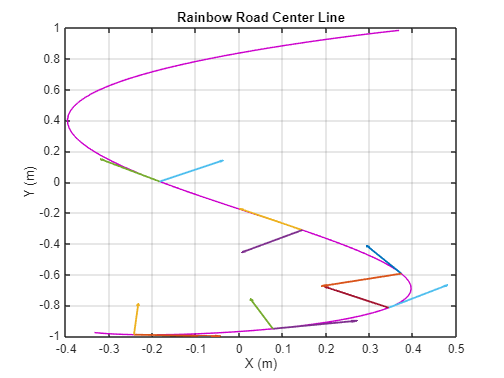



rainbow_road_center_line_x(u) = rainbow_road_center_line(1);
rainbow_road_center_line_y(u) = rainbow_road_center_line(2);
rainbow_road_center_line_pos_data_x = double(rainbow_road_center_line_x(full_u_range));
rainbow_road_center_line_pos_data_y = double(rainbow_road_center_line_y(full_u_range));
rainbow_road_center_line_tangent_vec_x(u) = rainbow_road_center_line_tangent_vec(1);
rainbow_road_center_line_tangent_vec_y(u) = rainbow_road_center_line_tangent_vec(2);
rainbow_road_center_line_norm_vec_x(u) = rainbow_road_center_line_norm_vec(1);
rainbow_road_center_line_norm_vec_y(u) = rainbow_road_center_line_norm_vec(2);

figure;
plot(rainbow_road_center_line_pos_data_x, rainbow_road_center_line_pos_data_y, Color=[0.8, 0, 0.8]); hold on
    for data_val = 5:10:60
        quiver( ...
            rainbow_road_center_line_pos_data_x(data_val), ...
            rainbow_road_center_line_pos_data_y(data_val), ...
            double(rainbow_road_center_line_tangent_vec_x(full_u_range(data_val))), ...
            double(rainbow_road_center_line_tangent_vec_y(full_u_range(data_val))), ...
            0.20, ...
            LineWidth=1.5 ...
        )
        quiver( ...
            rainbow_road_center_line_pos_data_x(data_val), ...
            rainbow_road_center_line_pos_data_y(data_val), ...
            double(rainbow_road_center_line_norm_vec_x(full_u_range(data_val))), ...
            double(rainbow_road_center_line_norm_vec_y(full_u_range(data_val))), ...
            0.20, ...
            LineWidth=1.5 ...
        )
    end
    title("Rainbow Road Center Line")
    xlabel("X (m)"); ylabel("Y (m)")
    grid on
hold off


plot(full_u_range, double(subs(rainbow_road_center_line_speed, u, full_u_range))); hold on
    title("Linear Speed and Angular Velocity")
hold off
